# **Programación en Matlab**

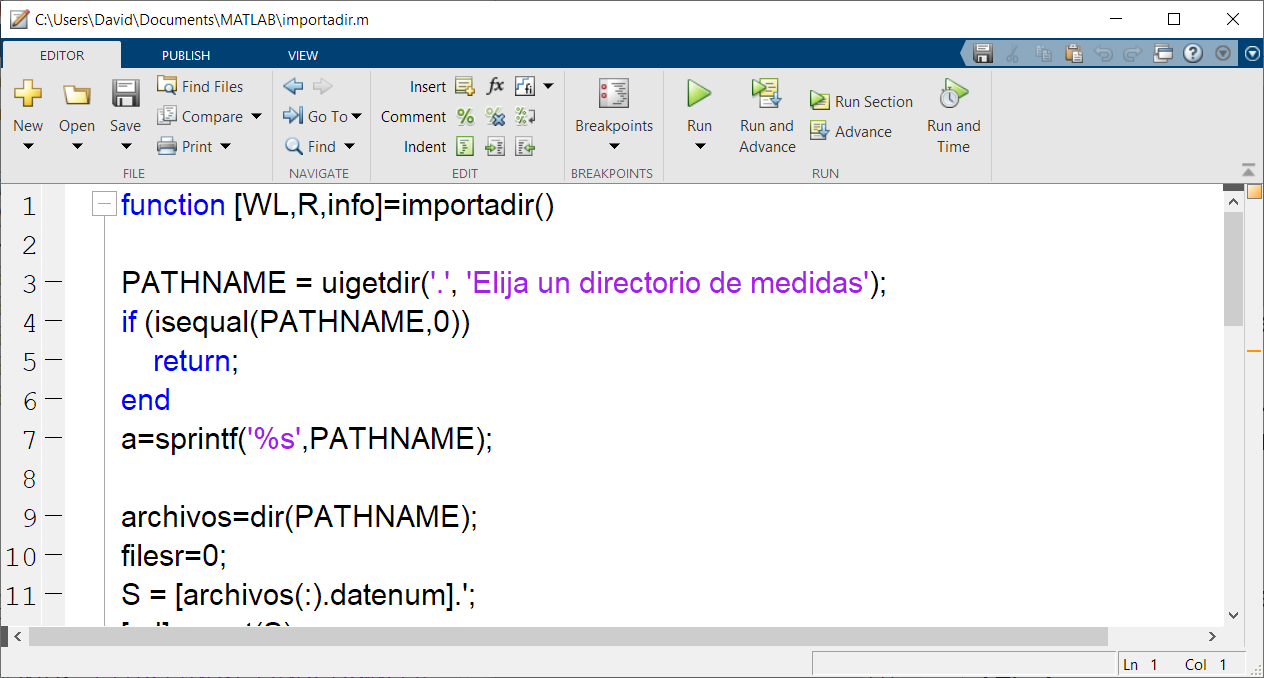

## **Introducción**

En Matlab, los programas se guardan en ficheros con extensión .m

Podemos distinguir dos tipos de programas, los scripts y las funciones.

## **Scripts**

Los *scripts* contienen un conjunto de comandos que se ejecutan sucesivamente. No aceptan argumentos de entrada ni devuelven argumentos de salida y operan sobre datos en el área de trabajo.

Hasta ahora hemos trabajado con *Live scripts*, que son scripts con una capacidad de depuración y edición avanzada, permitiendo que la salida se muestre en el mismo documento.

Cualquier *script* o función se puede guardar como *Live Script* o *Live Function* (.mlx). 

% Dentro de un fichero .m puedes incluir comentarios 
% Para ello debes introducir un %

velocidad = 100;   
tiempo = 1:50;     
velocidadms = velocidad/3.6;
posicion = velocidadms*tiempo

posicion =           27.7777777777778          55.5555555555556          83.3333333333333          111.111111111111          138.888888888889          166.666666666667          194.444444444444          222.222222222222                       250          277.777777777778          305.555555555556          333.333333333333          361.111111111111          388.888888888889          416.666666666667          444.444444444444          472.222222222222                       500          527.777777777778          555.555555555556          583.333333333333          611.111111111111          638.888888888889          666.666666666667          694.444444444444          722.222222222222                       750          777.777777777778          805.555555555556          833.333333333333          861.111111111111          888.888888888889          916.666666666667          944.444444444444          972.222222222222                      1000          1027.77777777778          1055.55555555556 

Para ejecutar un script o una función debemos introducir su nombre desde la línea de comandos o podemos pulsar el botón *Run*.

## Funciones

Son ficheros con una estructura especial. Con carácter general, una función recibe unos datos de entrada, ejecuta unas órdenes y produce unos datos de salida. Una función tendrá la siguiente estructura:

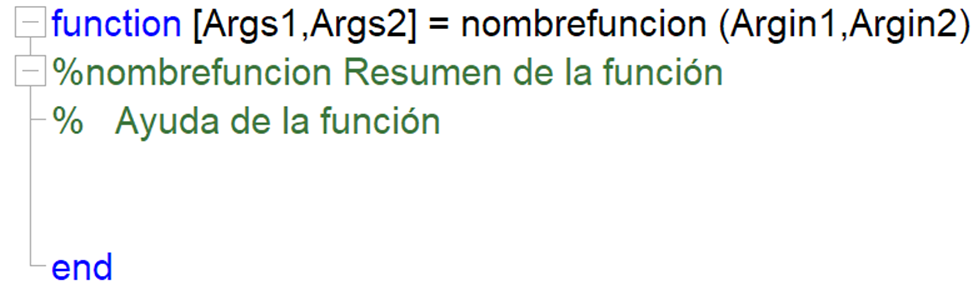

Para llamar a una función escribimos su nombre y los argumentos de entrada y salida como con cualquier otra función de MATLAB. 

>> v = 100;

>> t = 50;

>> Distanciarecorrida = calcularDistancia(v, t);

Se puede obtener el código de una función a través del comando *type *y la ayuda a través del comando* help.*

## Variables locales y globales

Las variables declaradas dentro de una función son variables locales (sólo estarán disponibles dentro de la función). Una alternativa es declarar variables globales. 

global x;

Al declara una variable como global, estará disponible para cualquier función.

## **Funciones anónimas**

Se pueden crear funciones simples de manera mucho más rápida mediante el uso de las funciones anónimas.

Las funciones anónimas no se guardan en un archivo y se asocian a una variable de tipo *function handle*.

Solo permiten tener una instrucción. En la definición de estas funciones el carácter @ indica la creación del *function handle*. Si tuviera parámetros de entrada se especifican entre los paréntesis y separados por comas.  

areaCirculo = @(r) pi*r^2;
A1 = areaCirculo(3)

A1 =           28.2743338823081


area = @(x,r) pi*x/360*r^2;
A2 = area(100,2)

A2 =           3.49065850398866


## **Funciones locales**

Un archivo .m puede contener más de una función. En un archivo de función, la primera función del archivo se llama la **función principal** (visible desde otros archivos o desde la línea de comandos). Las funciones adicionales dentro del archivo se llaman **funciones locales** (sólo son visibles para otras funciones del mismo archivo). 

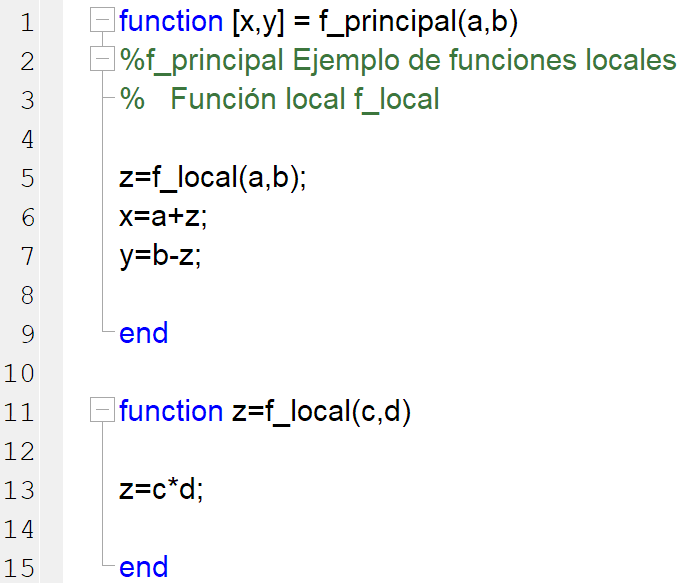

## **Funciones anidadas**

Una función anidada es una función que está completamente contenida dentro de una función principal. La mayor diferencia respecto a las funciones locales es que pueden acceder y modificar variables definidas en sus funciones primarias.

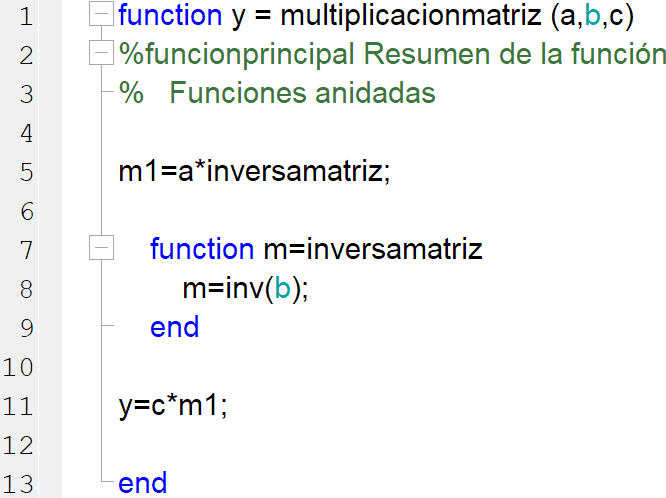

En el ejemplo anterior, el parámetro de entrada b es accesible desde la función anidada sin necesidad de pasarla como argumento de entrada a la función anidada. Note que el color por defecto de la variable cambia para indicar que el ámbito de la variable abarca más de una función.

## **Sentencias condicionales**

Las instrucciones condicionales permiten seleccionar en tiempo de ejecución el bloque de código que se ejecutará. Las instrucciones condicionales más usadas son el bloque *if* y el bloque *switch*.

Para ejecutar sentencias condicionales se requiere conocer algunos de las siguientes estructuras:

- **Operadores relacionales:** *>, >=, <, <=, ==, ~=*.

-  **Operadores lógicos:** *&* (AND), *|* (OR), *~ *(NOT), *xor* (OR exclusiva). Usando la expresión doble && o ||, sólo se evalúa si la primera parte cumple la condición. 

- **Funciones lógicas:** *any* (devuelve verdadero si algún valor cumple la condición), *all* (devuelve verdadero si todos los valores cumplen la condición), find (devuelve el índice de los elementos que cumplen la condición. 

array = randi([0 20], 1, 10)

array =     17    19     2    19    13     2     5    11    20    20


all(array~=0)

ans = logical
   1


any (array==3 | array == 7)

ans = logical
   0


find(array>8 & array<15)

ans =      5     8


### **Bloque if**

Se ejecuta un bloque de instruciones si la sentencia es verdadera. Se puede incluir un bloque *elseif* (para añadir una nueva condición) y *else* (para ejecutar si no se cumplen las expresiones anteriores). La estructura es:

                ***if**** expresion*

*                    bloque1*

                ***elseif**** expresion*

*                    bloque2*

                ***else***

*                    bloque3*

                ***end***

x = randi([1 100])

x =     16


if (rem(x,2) == 0)
    disp('x es un número par')
else
    disp('x es un número impar')
end

x es un número par


### **Bloque Switch**

Se utiliza para seleccionar uno de varios bloques de instrucciones. Su estructura es: 

            ***switch**** expresión*

               ***case**** caso1*

*                  bloque1*

               ***case**** caso2*

*                  bloque2*

               ***otherwise***

*                  bloqueAlternativo*

            ***end***

n = input('Introduce un numero: ');

switch n
    case {-1,-2}
        disp('1 o 2 negativo')
    case 0
        disp('cero')
    case {1,2}
        disp('1 o 2 positivo')
    otherwise
        disp('otro valor')
end

otro valor


## Bucles

Las instrucciones condicionales permiten ejecutar varias veces un bloque de código. Hay dos tipos de bucles fundamentales que son el bucle *for* y el bucle *while*.

### Bucle for

Repite las instrucciones un número determinado de veces. La sintaxis es:

***                for**** indice = valores*

*                   bloque1*

***                end***

donde valores puede ser un vector o serie. Veamos un ejemplo:

A = ones(1,20);
for v = 3:20
    A(v) = A(v-1)+A(v-2);
end
A

A =            1           1           2           3           5           8          13          21          34          55          89         144         233         377         610         987        1597        2584        4181        6765


### Bucle while

Repite una secuencia mientras se cumple una condición.

                ***while**** expresion*

*                    bloque1*

                ***end***

B = 0

B =      0


while (B<10 && B>-10)
    B = B + randi([-1 2])
end

B =      2


B =      4


B =      4


B =      6


B =      5


B =      5


B =      7


B =      9


B =     11


### **Otros comandos de control**

Podemos usar *break* (para interrumpir un bucle) o *continue* (para pasar al siguiente elemento).

while (true)
    A = input('Introduce un número del 1 al 5: ');
    B = randi([1 5])
    if (A==B)
        break;
    end
end

B =      4



for i =1:5
    numero = input('Pulsa 1: ');
    if (numero==1)
        continue
    end
    %Esto no se ejecuta si has pulsado el 1
    r = i+i
end

## Gestión de argumentos

Podemos utilizar las siguientes funciones para gestionar los argumentos de entrada o salida en una función. 

        *nargin/nargout*: Devuelven el número de argumentos de entrada/salida.

                *varargin/varargout*: Lista de argumentos de entrada/salida.

                *narginchk/nargoutchk*: Verifica el número de argumentos de entrada/salida. 

## 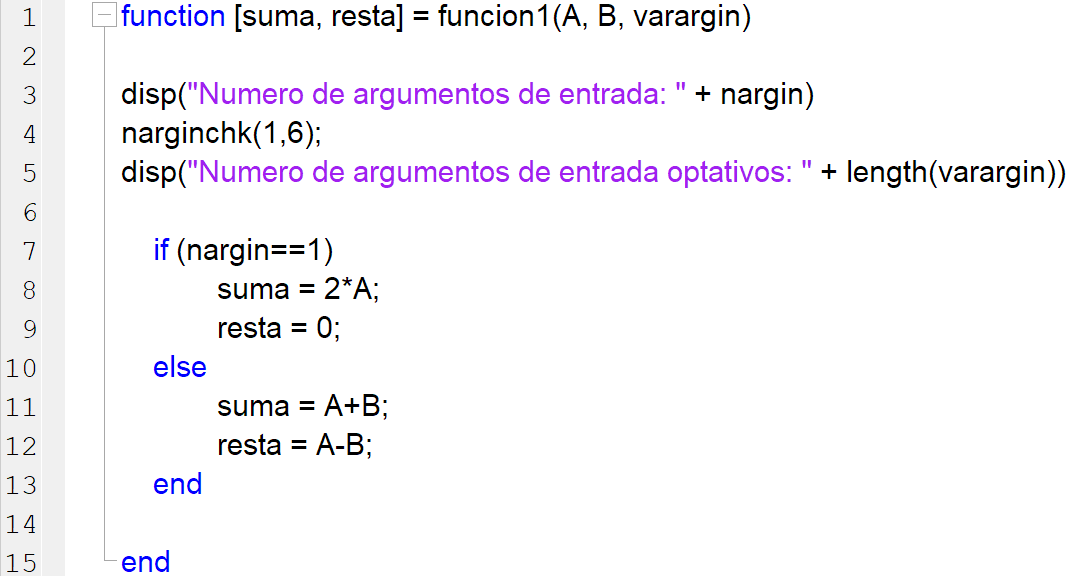

## Manejo de excepciones

Podemos utilizar el bloque *try/catch* para gestionar las excepciones. Si aparece un error dentro del bloque *try*, se ejecutará el boque *catch*.

***try***

*   statements*

***catch**** exception*

*   statements*

***end***

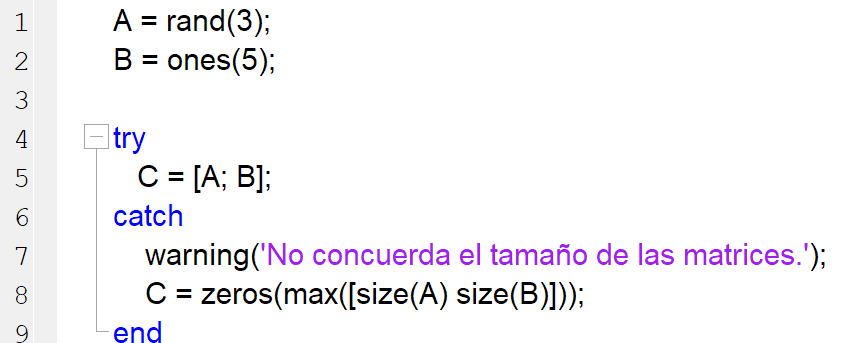

## Ejercicios

### Ejercicio 1

Considere un cono. Escriba una **función** de MATLAB que calcule y devuelva el volumen del cono dados el radio ***r ***y la altura ***h*** del cono como argumentos de entrada.


$$V=\frac{1}{3}\pi r^2 h$$


En primer lugar, la función deberá comprobar que el tanto el radio como la altura son escalares positivos.

clc;clear;

% type nombredelafuncion
r = 25;
h = 10;

volumen_cono = calculo_volumen_cono("r",h)

volumen_cono = "No es posible calcularlo"

### Ejercicio 2

Escriba una función que tenga como entrada dos valores y devuelva una matriz cuadrada. El primer argumento de entrada indicará el tamaño de la matriz. El segundo argumento ***x***, servirá para calcular los elementos de la matriz tal que: 


$$\left\lbrack \begin{array}{ccccccc}
1 & x & x^2  & \cdots  & \cdots  & x^{n-2}  & x^{n-1} \\
x & x^2  & \cdots  & \ddots  & x^{n-2}  & x^{n-1}  & x^{n-2} \\
x^2  & \cdots  & \ddots  & x^{n-2}  & x^{n-1}  & x^{n-2}  & \vdots \\
\vdots  & \ddots  & x^{n-2}  & x^{n-1}  & x^{n-2}  & \ddots  & \vdots \\
\vdots  & x^{n-2}  & x^{n-1}  & x^{n-2}  & \ddots  & \cdots  & x^2 \\
x^{n-2}  & x^{n-1}  & x^{n-2}  & \ddots  & \cdots  & x^2  & x\\
x^{n-1}  & x^{n-2}  & \cdots  & \cdots  & x^2  & x & 1
\end{array}\right\rbrack$$


type nombredelafuncion

Error using type
File 'nombredelafuncion' not found.

### Ejercicio 3

Escriba una función que calcule y dibuje la siguiente función entre 0 y 10:


$$y=\sin \left(2\pi \cdot \textrm{f1}\cdot t+a\right)+\cos \left(2\pi \cdot \textrm{f2}\cdot t+b\right)$$


La función tendrá cuatro parámetros de entrada: f1,f2,a y b. Siendo f1, f2 escalares positivos que representan las frecuencias de las sinusoides y a,b también dos escalares que representan la fase de las señales. *t* representa el tiempo.

La función devolverá el valor de la función (y).

Recuerde añadir las etiquetas a los ejes.

type nombredelafuncion



### Ejercicio 4

Escriba una función *myorder* que ordene un vector de escalares. Esta función tendrá como mínimo un parámetro  de entrada que será el vector. Si se llama a la función con un único parámetro de entrada la función recorrerá el vector y ordenará sus elementos de mayor a menor. Si se llama a la función con dos parámetros de entrada el segundo argumento aceptará una cadena de caracteres cuyo valor puede ser 'ascendente' o 'descendente', y en función de este valor ordenará el vector de menor a mayor o de mayor a menor, respectivamente. En ambos casos la función debe devolver un vector ordenado. Use la función ***sort*** dentro de su función.

type nombredelafuncion


